## Load & Structure Human Data

% clear all;

load('./completeData/human_data')

addpath(genpath('matlabfunctions'))
addpath(genpath('/Applications/MATLAB_TOOLBOXES'))

area_metric = 3; %1-smoothwm, 2-pial, 3-avg

disp(human_data.labels)

  Columns 1 through 13

    {'V1v'}    {'V1d'}    {'V2v'}    {'V2d'}    {'V3v'}    {'V3d'}    {'hV4'}    {'VO1'}    {'VO2'}    {'PHC1'}    {'PHC2'}    {'V3A'}    {'V3B'}

  Columns 14 through 24

    {'LO1'}    {'LO2'}    {'TO1'}    {'TO2'}    {'IPS0'}    {'IPS1'}    {'IPS2'}    {'IPS3'}    {'IPS4'}    {'IPS5'}    {'SPL1'}




% these numbers correspond to color-coded grouping of brain areas in plots
EVCrois_human=1:6; EVCcolor=[0 0 0.7];
V4rois_human=7; V4color=[0.6 0 0.6];
ventralrois_human=8:11; ventralcolor=[0.6 0.1 0.1];
dorsalrois_human=12:13; dorsalcolor=[0.8 .5 0]; % added V7, idk if that's right
lateralrois_human=14:17; lateralcolor=[0.2784    0.5216    0.1451];
parietalrois_human=18:24; parietalcolor=[0 0.7 0.7];

% concatenate all human area ROIs, labels, and colors
allrois_human = {EVCrois_human;V4rois_human;ventralrois_human;dorsalrois_human;lateralrois_human;parietalrois_human};
use_colorscale_human_all=[repmat(EVCcolor,length(EVCrois_human),1);...
    repmat(V4color,length(V4rois_human),1);...
    repmat(ventralcolor,length(ventralrois_human),1);...
    repmat(dorsalcolor,2,1);...
    repmat(lateralcolor,length(lateralrois_human),1);...
    repmat(parietalcolor,length(parietalrois_human),1)];

% actual full brain surface area
total_area_cat_human = [human_data.total_size(:,1)' human_data.total_size(:,2)'];

% Make 0 sum ROIs -> NaN
for i = 1:2
    human_data.surfacearea_smoothwm{i}(human_data.surfacearea_smoothwm{i}==0)=nan;
    human_data.surfacearea_pial{i}(human_data.surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
surfacearea_avg = cellfun(@(x,y) (x+y)/2, human_data.surfacearea_smoothwm, human_data.surfacearea_pial,'UniformOutput',false);

% get sum and concatenated hemispheres depending on area metric
if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis_human = human_data.surfacearea_smoothwm{1} + human_data.surfacearea_smoothwm{2};
    surfacearea_catbothhemis=cat(2,human_data.surfacearea_smoothwm{1},human_data.surfacearea_smoothwm{2});
    surfacearea_human = human_data.surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis_human = human_data.surfacearea_pial{1} + human_data.surfacearea_pial{2};
    surfacearea_catbothhemis=cat(2,human_data.surfacearea_pial{1},human_data.surfacearea_pial{2});
    surfacearea_human = human_data.surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis_human = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea_human = surfacearea_avg;
end


## Humans: Set Up Categories of Regions

mean_areas_bothhemis = nanmean(surfacearea_bothhemis_human,2); %take average for each visual area across subject 
stderror_areas_bothhemis = nanstd(surfacearea_bothhemis_human,0,2) / sqrt(size(surfacearea_bothhemis_human,1)); %find SE of surface area size for visual areas

% restructure data to get area categories we want to display
V1_bothhemis_combined = surfacearea_bothhemis_human(1,:) + surfacearea_bothhemis_human(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis_human(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis_human(5:6,:),1);
V4_bothhemis_combined = surfacearea_bothhemis_human(7,:);

v_human = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;surfacearea_bothhemis_human(8:end,:)];

% average over broad areas for raw surface area measurements
ventral_combined_human = mean(v_human(ventralrois_human-3,:),1);
dorsal_combined_human = mean(v_human(dorsalrois_human-3,:),1);
lateral_combined_human = mean(v_human(lateralrois_human-3,:),1);
parietal_combined_human = mean(v_human(parietalrois_human-3,:),1);

v_combined_human = [v_human(1:4,:);ventral_combined_human;dorsal_combined_human;...
    lateral_combined_human;parietal_combined_human];

%combined hemis V1
normv1_human = v_human./V1_bothhemis_combined;

% average over broad regions for surface area measurements relative to V1
normventral_combined_human = mean(normv1_human(ventralrois_human-3,:),1);
normdorsal_combined_human = mean(normv1_human(dorsalrois_human-3,:),1);
normlateral_combined_human = mean(normv1_human(lateralrois_human-3,:),1);
normparietal_combined_human = mean(normv1_human(parietalrois_human-3,:),1);

normv1_combined_human = [normv1_human(1:4,:);normventral_combined_human;normdorsal_combined_human;...
    normlateral_combined_human;normparietal_combined_human];

use_colorscale_human=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];
use_colorscale_unique_human = unique(use_colorscale_human,'stable','rows');
use_colorscale_inv_human = flipud(use_colorscale_human);

alllabels_human = human_data.labels;
alllabels_humans_general = {'V1','V2','V3','V4','Ventral','Dorsal','Lateral','Parietal'};

## Load & Structure Monkey Data

load('./completeData/monkey_data')

area_metric = 3; %1-smoothwm, 2-pial, 3-avg

% these numbers correspond to visual area labels (second column of roi)
alllabels_monkey={'V1v','V1d','V2v','V2d','V3v','V3d','V4v','V4d','V4Av','V4Ad','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','MT','MST','FST','V4t','CIP1','CIP2','LIP1','LIP2','LIP3'};       

% these numbers correspond to color-coded grouping of brain areas in plots
EVCrois_monkey=1:6; EVCcolor=[0.1 0.6 1];
V4rois_monkey=7:10; V4color=[1 0.2 1];
ventralrois_monkey=11:15; ventralcolor=[1 0.2 0.2];
dorsalrois_monkey=16:17; dorsalcolor=[1 .8 0];
lateralrois_monkey=18:21; lateralcolor=[0 1 0];
parietalrois_monkey=22:26; parietalcolor=[0 1 1];

% concatenate all human area ROIs, labels, and colors
allrois_monkey = {EVCrois_monkey;V4rois_monkey;ventralrois_monkey;dorsalrois_monkey;parietalrois_monkey;lateralrois_monkey};
use_colorscale_monkey_all=[repmat(EVCcolor,length(EVCrois_monkey),1);...
    repmat(V4color,length(V4rois_monkey),1);...
    repmat(ventralcolor,length(ventralrois_monkey),1);...
    repmat(dorsalcolor,length(dorsalrois_monkey),1);...
    repmat(lateralcolor,length(lateralrois_monkey),1);...
    repmat(parietalcolor,length(parietalrois_monkey),1)];
use_colorscale_unique_monkey = unique(use_colorscale_monkey_all,'stable','rows');

% rename areas to match human code
for i = 1:2
    surfacearea_monkey_total{i} = monkey_data.retino_surfacearea_total{i};
    surfacearea_smoothwm{i} = monkey_data.retino_surfacearea_smoothwm{i};
    surfacearea_pial{i} = monkey_data.retino_surfacearea_pial{i};
end
% sum over hemispheres
total_surfacearea_bothhemis=surfacearea_monkey_total{1}+surfacearea_monkey_total{2};

% actual full brain surface area
total_area_cat_monkey = [monkey_data.total_size(:,1)' monkey_data.total_size(:,2)'];

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end
% get average of white matter and pial surface area
surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

% get sum and concatenated hemispheres depending on area metric
if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis_monkey = surfacearea_smoothwm{1} + surfacearea_smoothwm{2};
    surfacearea_catbothhemis=cat(2,surfacearea_smoothwm{1},surfacearea_smoothwm{2});
    surfacearea_monkey = surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis_monkey = surfacearea_pial{1} + surfacearea_pial{2};
    surfacearea_catbothhemis=cat(2,surfacearea_pial{1},surfacearea_pial{2});
    surfacearea_monkey = surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis_monkey = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea_monkey = surfacearea_avg;
end

## Monkeys: Set Up Categories of Regions

mean_areas_bothhemis = nanmean(surfacearea_bothhemis_monkey,2); %take average for each visual area across subject 
stderror_areas_bothhemis = nanstd(surfacearea_bothhemis_monkey,0,2) / sqrt(size(surfacearea_bothhemis_monkey,1)); %find SE of surface area size for visual areas

% restructure data to get area categories we want to display
V1_bothhemis_combined = surfacearea_bothhemis_monkey(1,:) + surfacearea_bothhemis_monkey(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis_monkey(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis_monkey(5:6,:),1);
V4_bothhemis_combined = sum(surfacearea_bothhemis_monkey(7:8,:),1);
V4A_bothhemis_combined = sum(surfacearea_bothhemis_monkey(9:10,:),1);

v_monkey = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;V4A_bothhemis_combined;surfacearea_bothhemis_monkey(11:end,:)];

% average over broad areas for raw surface area measurements
V4_combined_monkey = mean(v_monkey(4:5,:),1);
ventral_combined_monkey = mean(v_monkey(ventralrois_monkey-5,:),1);
dorsal_combined_monkey = mean(v_monkey(dorsalrois_monkey-5,:),1);
lateral_combined_monkey = mean(v_monkey(lateralrois_monkey-5,:),1);
parietal_combined_monkey = mean(v_monkey(parietalrois_monkey-5,:),1);

v_combined_monkey = [v_monkey(1:3,:);V4_combined_monkey;ventral_combined_monkey;...
    dorsal_combined_monkey;lateral_combined_monkey;parietal_combined_monkey];

%combined hemis V1
normv1_monkey = v_monkey./V1_bothhemis_combined;

% average over broad regions for surface area measurements relative to V1
normV4_combined_monkey = mean(normv1_monkey(4:5,:),1);
normventral_combined_monkey = mean(normv1_monkey(ventralrois_monkey-5,:),1);
normdorsal_combined_monkey = mean(normv1_monkey(dorsalrois_monkey-5,:),1);
normlateral_combined_monkey = mean(normv1_monkey(lateralrois_monkey-5,:),1);
normparietal_combined_monkey = mean(normv1_monkey(parietalrois_monkey-5,:),1);

normv1_combined_monkey = [normv1_monkey(1:3,:);normV4_combined_monkey;normventral_combined_monkey;...
    normdorsal_combined_monkey;normlateral_combined_monkey;normparietal_combined_monkey];

use_colorscale_monkey=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];
use_colorscale_unique_monkey = unique(use_colorscale_monkey,'stable','rows');
use_colorscale_inv_monkey = flipud(use_colorscale_monkey);

alllabels_monkey = {'V1','V2','V3','V4','V4A','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','MT','MST','FST','V4t','CIP1','CIP2','LIP1','LIP2','LIP3'};       
alllabels_monkeys_general = {'V1','V2','V3','V4','Ventral','Dorsal','Lateral','Parietal'};
alllabels_combined = {'V1','V1','V2','V2','V3','V3','V4','V4','Ventral','Ventral','Dorsal','Dorsal','Lateral','Lateral','Parietal','Parietal'};

## Set up struct for visualization

human_fig_data = table;
monkey_fig_data = table;

human_fig_region_data = table;
monkey_fig_region_data = table;

% save('./data/human_fig_data.mat','human_fig_data')
% save('./data/monkey_fig_data.mat','monkey_fig_data')
% save('./data/human_fig_region_data.mat','human_fig_region_data')
% save('./data/monkey_fig_region_data.mat','monkey_fig_region_data')


## Fig 2A&B: Plot Raw Surface Area Comparisons

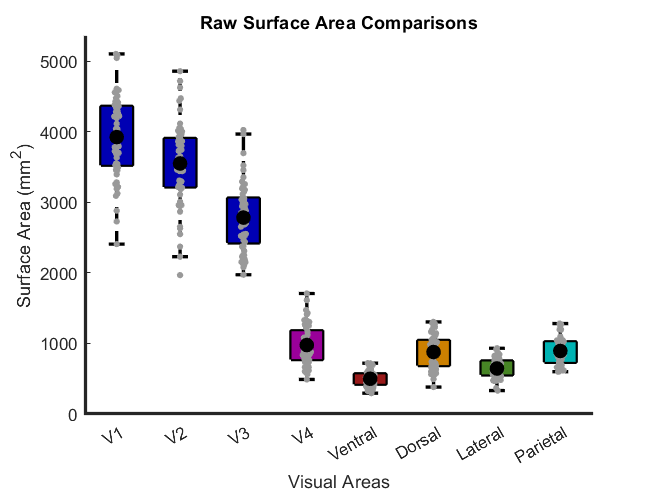

human_fig_region_data = array2table(mean(v_combined_human,2,'omitnan'),"RowNames",alllabels_humans_general,"VariableNames","Raw Surface Area");

figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
hold on
h1=boxplot(v_combined_human','positions',1:2:size(v_combined_human,1)*2,'notch','off','colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(v_combined_human,1)
   patch(get(h1(j),'XData'),get(h1(j),'YData'),use_colorscale_inv_human(j,:),'FaceAlpha',1);
end
plotSpread(v_combined_human','xValues',1:2:size(v_combined_human,1)*2,'distributionColors',use_colorscale_human*0+[.6 .6 .6],'spreadWidth',.5)
plot(1:2:size(v_combined_human,1)*2,nanmean(v_combined_human'),'k.','MarkerSize',30);
% xlim([0.5 size(normv1_combined_human,1)+.5])

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:2:length(alllabels_humans_general)*2],'xticklabel', alllabels_humans_general,'ytick',0:1000:5000);
xlabel('Visual Areas');
ylabel('Surface Area (mm^2)');
title('Raw Surface Area Comparisons')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

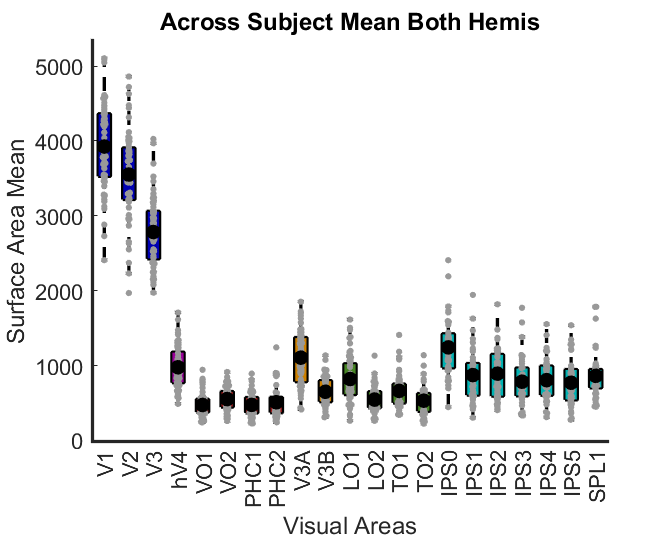


%% Plot distributions of area sizes
sum_dv = zeros(size(surfacearea_bothhemis_human,1)-3,size(surfacearea_bothhemis_human,2));
sum_dv(1,:) = sum(surfacearea_bothhemis_human(1:2,:));
sum_dv(2,:) = sum(surfacearea_bothhemis_human(3:4,:));
sum_dv(3,:) = sum(surfacearea_bothhemis_human(5:6,:));
sum_dv(4:end,:) = surfacearea_bothhemis_human(7:end,:);

alllabs = cat(2,{'V1','V2','V3'},alllabels_human(7:end));

human_fig_data = array2table(mean(sum_dv,2,'omitnan'),"RowNames",alllabs,"VariableNames","Raw Surface Area");

use_colorscale_inv_all=flipud(use_colorscale_human_all);
figure
hold on
h=boxplot(sum_dv','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),(use_colorscale_inv_all(j,:)),'FaceAlpha',1);
end
hold on
plotSpread(sum_dv','distributionColors',use_colorscale_human_all(4:end,:)*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(sum_dv'),'k.','MarkerSize',30);
xlim([0.5 size(sum_dv,1)+.5])
yticks(0:1000:5000)
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
ax.FontSize = 13;
set(gca,'xtick',[1:length(alllabs)],'xticklabel', alllabs);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean Both Hemis')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]); 

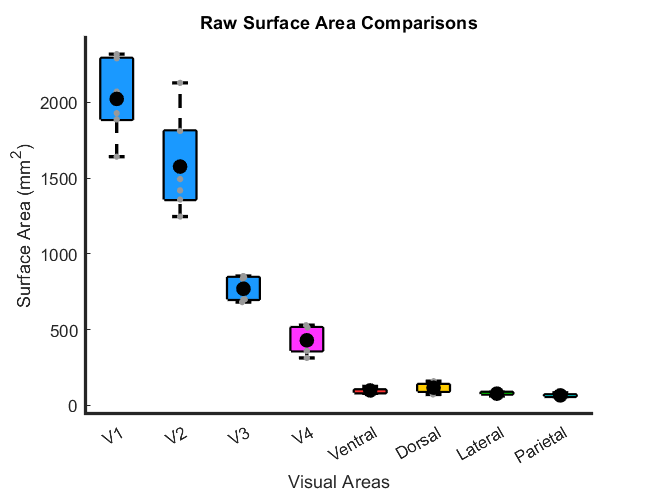

monkey_fig_region_data = array2table(mean(v_combined_monkey,2,'omitnan'),"RowNames",alllabels_monkeys_general,"VariableNames","Raw Surface Area");

figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
hold on
h2=boxplot(v_combined_monkey','positions',1:2:size(v_combined_monkey,1)*2,'notch','off','colors',[0 0 0],'symbol','');
set(h2,{'linew'},{2})
h2 = findobj(gca,'Tag','Box');
for j=1:size(v_combined_monkey,1)
   patch(get(h2(j),'XData'),get(h2(j),'YData'),use_colorscale_inv_monkey(j,:),'FaceAlpha',1);
end
plotSpread(v_combined_monkey','xValues',1:2:size(v_combined_monkey,1)*2,'distributionColors',use_colorscale_monkey*0+[.6 .6 .6],'spreadWidth',.5)
plot(1:2:size(v_combined_monkey,1)*2,nanmean(v_combined_monkey'),'k.','MarkerSize',30);
hold on

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:2:length(alllabels_monkeys_general)*2],'xticklabel', alllabels_monkeys_general,'ytick',0:500:2000);
xlabel('Visual Areas');
ylabel('Surface Area (mm^2)');
title('Raw Surface Area Comparisons')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

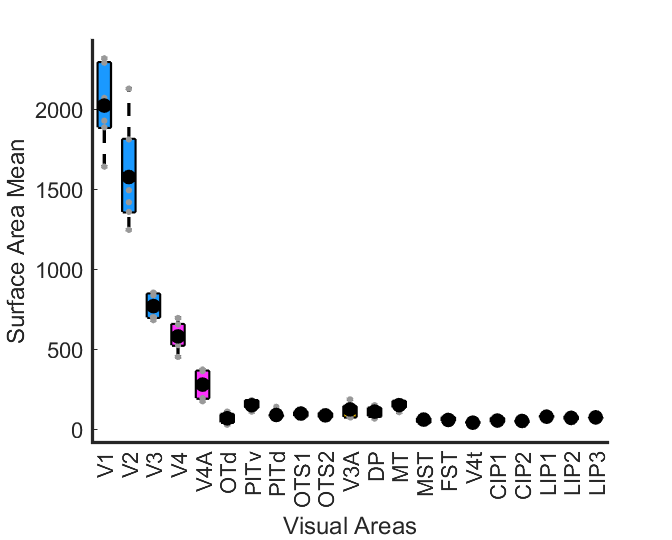

%% Plot distributions of area sizes
sum_dv = zeros(size(surfacearea_bothhemis_monkey,1)-5,size(surfacearea_bothhemis_monkey,2));
sum_dv(1,:) = sum(surfacearea_bothhemis_monkey(1:2,:));
sum_dv(2,:) = sum(surfacearea_bothhemis_monkey(3:4,:));
sum_dv(3,:) = sum(surfacearea_bothhemis_monkey(5:6,:));
sum_dv(4,:) = sum(surfacearea_bothhemis_monkey(7:8,:));
sum_dv(5,:) = sum(surfacearea_bothhemis_monkey(9:10,:));
sum_dv(6:end,:) = surfacearea_bothhemis_monkey(11:end,:);

alllabs = cat(2,{'V1','V2','V3','V4','V4A'},alllabels_monkey(6:end));

monkey_fig_data = array2table(mean(sum_dv,2,'omitnan'),"RowNames",alllabs,"VariableNames","Raw Surface Area");

cmonkey = [use_colorscale_monkey_all(1:3,:);use_colorscale_monkey_all(7:8,:);use_colorscale_monkey_all(11:end,:)];

use_colorscale_inv_all=flipud(cmonkey);
figure
hold on
h=boxplot(sum_dv','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),(use_colorscale_inv_all(j,:)),'FaceAlpha',1);
end
hold on
cscale = zeros(size(use_colorscale_monkey_all,1)-5,3);
plotSpread(sum_dv','distributionColors',cscale+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(sum_dv'),'k.','MarkerSize',30);
xlim([0.5 size(sum_dv,1)+.5])
yticks(0:500:2000)
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
ax.FontSize = 13;
set(gca,'xtick',[1:length(alllabs)],'xticklabel', alllabs);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
% title('Across Subject Mean Both Hemis')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

## Fig 2C: Plot Normalized Surface Area Comparisons

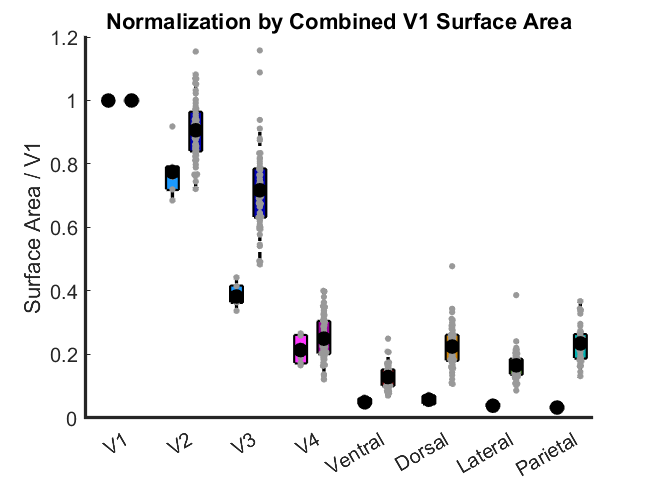

human_fig_region_data = [human_fig_region_data array2table(mean(normv1_combined_human,2,'omitnan'),"VariableNames","Surface Area / V1")];
monkey_fig_region_data = [monkey_fig_region_data array2table(mean(normv1_combined_monkey,2,'omitnan'),"VariableNames","Surface Area / V1")];

% pad array with nan to get the same size as humans
addnanmonkey = padarray(normv1_combined_monkey,[1 size(normv1_combined_human,2) - size(normv1_combined_monkey,2)],nan,'post');
concat_data = [];
concat_colorscale = [];
for i = 1:size(normv1_combined_human,1)
    concat_data = [concat_data; addnanmonkey(i,:); normv1_combined_human(i,:)];
    concat_colorscale = [concat_colorscale;use_colorscale_inv_human(i,:);use_colorscale_inv_monkey(i,:)];
end

% set groupings by species and areas to use factorgap in boxplot
g1 = sort([1:8,1:8]);
g2 = repmat(1:2,[1,8]);

figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
hold on
h1=boxplot(concat_data',[g1' g2'],'factorgap',5,'colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(concat_data,1)
   % have to extract x values from boxplot in order to set xlabels
   xdat{j} = get(h1(j),'XData');
   xd(j) = (xdat{j}(3)+xdat{j}(2))/2;
   patch(get(h1(j),'XData'),get(h1(j),'YData'),concat_colorscale(j,:),'FaceAlpha',1);
end

plotSpread(concat_data','xValues',fliplr(xd),'distributionColors',concat_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(fliplr(xd),nanmean(concat_data'),'k.','MarkerSize',30);

% take average of x values for each area to put xticklabel in the middle
xt = [];
for i = 1:length(xd)/2
    xt(i) = (xd(2*i-1) + xd(2*i))/2;
end

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',fliplr(xt),'xticklabel', alllabels_combined(1:2:end),'fontsize',12);
% xlabel('Visual Areas');
ylabel('Surface Area / V1');
title('Normalization by Combined V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
ylim([0 1.2])

## Fig 3: Plot Cross-hemisphere Correlations - Normalized

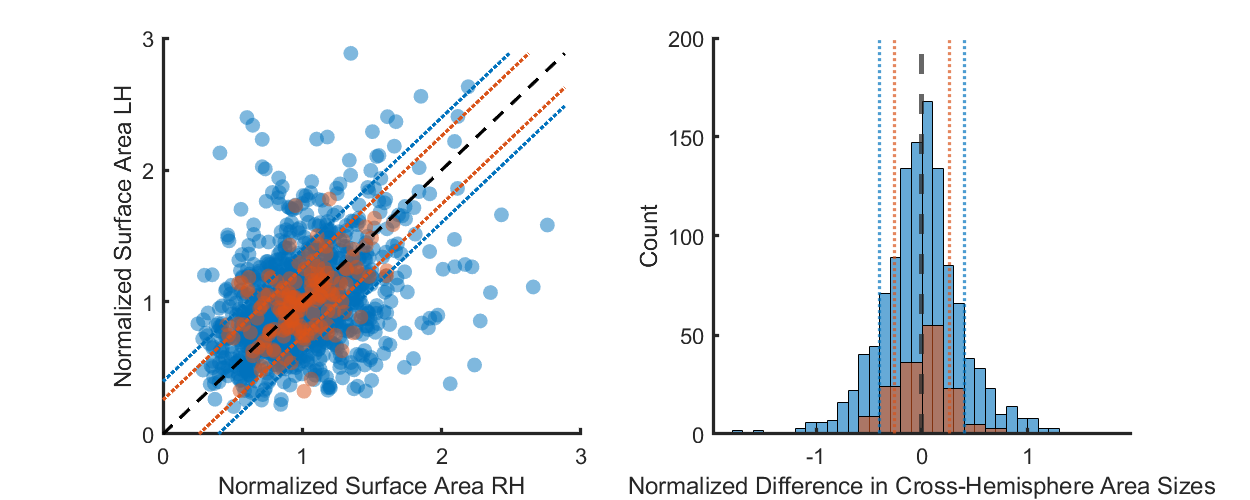

surfacearea_human_norm{1} = surfacearea_human{1}(1:end-2,:) ./ mean(surfacearea_human{1}(1:end-2,:),2,'omitnan');
surfacearea_human_norm{2} = surfacearea_human{2}(1:end-2,:) ./ mean(surfacearea_human{2}(1:end-2,:),2,'omitnan');

surfacearea_monkey_norm{1} = surfacearea_monkey{1} ./ mean(surfacearea_monkey{1},2,'omitnan');
surfacearea_monkey_norm{2} = surfacearea_monkey{2} ./ mean(surfacearea_monkey{2},2,'omitnan');

humanvar = var(surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:),'omitnan');
humanstd = std(surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:),'omitnan');
monkvar = var(surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:),'omitnan');
monkstd = std(surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:),'omitnan');

data1 = surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:);
data2 = surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:);
include = ~isnan(data1);data1 = data1(include);
include = ~isnan(data2);data2 = data2(include);
[h,p] = vartest2(data1, data2);
% disp([h, p])

figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
subplot(1,2,1)
s1 = scatter(surfacearea_human_norm{1}(:),surfacearea_human_norm{2}(:),80,'filled');
s1.MarkerFaceAlpha = 0.5;
hold on;
s2 = scatter(surfacearea_monkey_norm{1}(:),surfacearea_monkey_norm{2}(:),80,'filled');
s2.MarkerFaceAlpha = 0.5;
max_value=max([max(surfacearea_human_norm{1}(:)),max(surfacearea_human_norm{2}(:))]);
min_value=floor([min(surfacearea_human_norm{1}(:)),min(surfacearea_human_norm{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
plot([min_value, max_value-humanstd],[min_value+humanstd,max_value],':','Color',[0 0.4470 0.7410],'LineWidth',2)
plot([min_value+humanstd, max_value],[min_value,max_value-humanstd],':','Color',[0 0.4470 0.7410],'LineWidth',2)
plot([min_value, max_value-monkstd],[min_value+monkstd,max_value],':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot([min_value+monkstd, max_value],[min_value,max_value-monkstd],':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
xlabel('Normalized Surface Area RH')
ylabel('Normalized Surface Area LH')
% title(['Two Sample F Test: p = ',num2str(p)])
xticks(0:4)
yticks(0:4)
ax = gca;
ax.XAxis.LineWidth = 2;
ax.YAxis.LineWidth = 2;
ax.FontSize = 13;

subplot(1,2,2)
% figure('Renderer', 'painters', 'Position', [10 10 600 500]);
histogram((surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:)));
hold on;
histogram((surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:)));
xline(0,'--','linewidth',3)
xline(humanstd,':','Color',[0 0.4470 0.7410],'LineWidth',2)
xline(-humanstd,':','Color',[0 0.4470 0.7410],'LineWidth',2)
xline(monkstd,':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
xline(-monkstd,':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
box off
xlabel('Normalized Difference in Cross-Hemisphere Area Sizes')
ylabel('Count')
% legend('Humans','Monkeys')
% title(['Two Sample F Test: p = ',num2str(p)])
xticks(-2:2)
yticks(0:50:200)
ax = gca;
ax.XAxis.LineWidth = 2;
ax.YAxis.LineWidth = 2;
ax.FontSize = 13;

disp(['Two Sample F Test: p = ',num2str(p)])

Two Sample F Test: p = 1.7983e-10


## Plot Cross-hemisphere Correlations

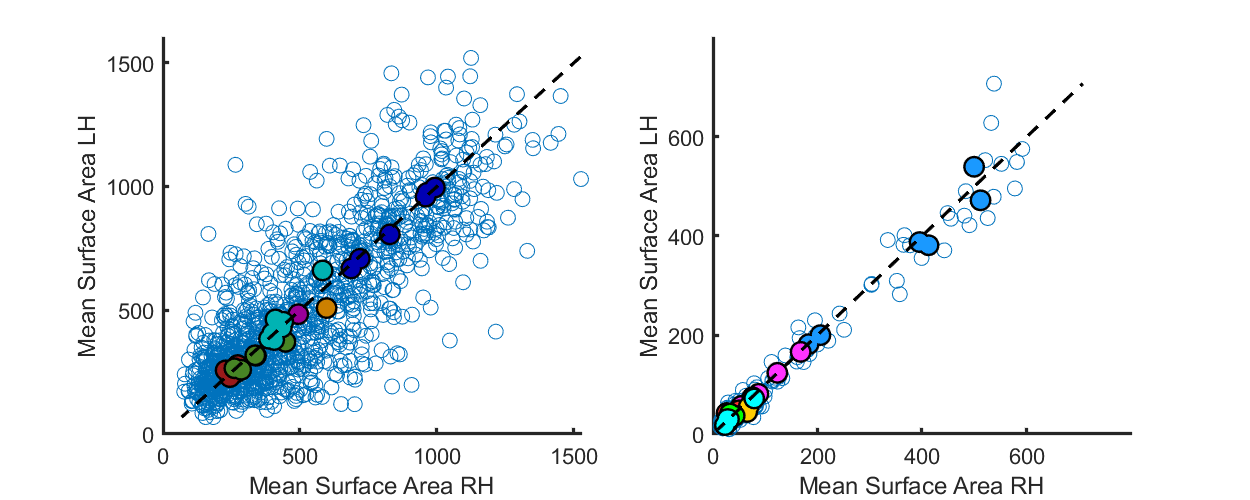

figure('Renderer', 'painters', 'Position', [10 10 1000 400])
subplot(1,2,1)
scatter(surfacearea_human{1}(:),surfacearea_human{2}(:),80);
hold on
for rr = 1:length(allrois_human)
    plot(nanmean(surfacearea_human{1}(allrois_human{rr},:),2),nanmean(surfacearea_human{2}(allrois_human{rr},:),2),'.k','MarkerSize',45);
    plot(nanmean(surfacearea_human{1}(allrois_human{rr},:),2),nanmean(surfacearea_human{2}(allrois_human{rr},:),2),'.','Color',use_colorscale_unique_human(rr,:),'MarkerSize',35);
end
max_value=max([max(surfacearea_human{1}(:)),max(surfacearea_human{2}(:))]);
min_value=floor([min(surfacearea_human{1}(:)),min(surfacearea_human{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
xlabel('Mean Surface Area RH');
ylabel('Mean Surface Area LH');
xticks(0:500:2000)
yticks(0:500:2000)
set(gca,'FontSize',13)
set(gca,'linewidth',2)
% set(gca,'XTick',[])
% set(gca,'YTick',[])
% title('Human Cross-Hemisphere Surface Area Correlation')


subplot(1,2,2)
scatter(surfacearea_monkey{1}(:),surfacearea_monkey{2}(:),80);
hold on
for rr = 1:length(allrois_monkey)
    plot(nanmean(surfacearea_monkey{1}(allrois_monkey{rr},:),2),nanmean(surfacearea_monkey{2}(allrois_monkey{rr},:),2),'.k','MarkerSize',45);
    plot(nanmean(surfacearea_monkey{1}(allrois_monkey{rr},:),2),nanmean(surfacearea_monkey{2}(allrois_monkey{rr},:),2),'.','Color',use_colorscale_unique_monkey(rr,:),'MarkerSize',35);
end
max_value=max([max(surfacearea_monkey{1}(:)),max(surfacearea_monkey{2}(:))]);
min_value=floor([min(surfacearea_monkey{1}(:)),min(surfacearea_monkey{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
xlabel('Mean Surface Area RH');
ylabel('Mean Surface Area LH');
xticks(0:200:600)
yticks(0:200:600)
set(gca,'FontSize',13)
% title('Monkey Cross-Hemisphere Surface Area Correlation')
set(gca,'linewidth',2)

[h,p] = vartest2(surfacearea_human{1}(:)-surfacearea_human{2}(:), surfacearea_monkey{1}(:)-surfacearea_monkey{2}(:));
disp([h, p])

    1.0000    0.0000



## Hemisphere Comparisons for Each Region

V1=1:2;
V2=3:4;

V2 =      3     4


V3=5:6;

V3 =      5     6


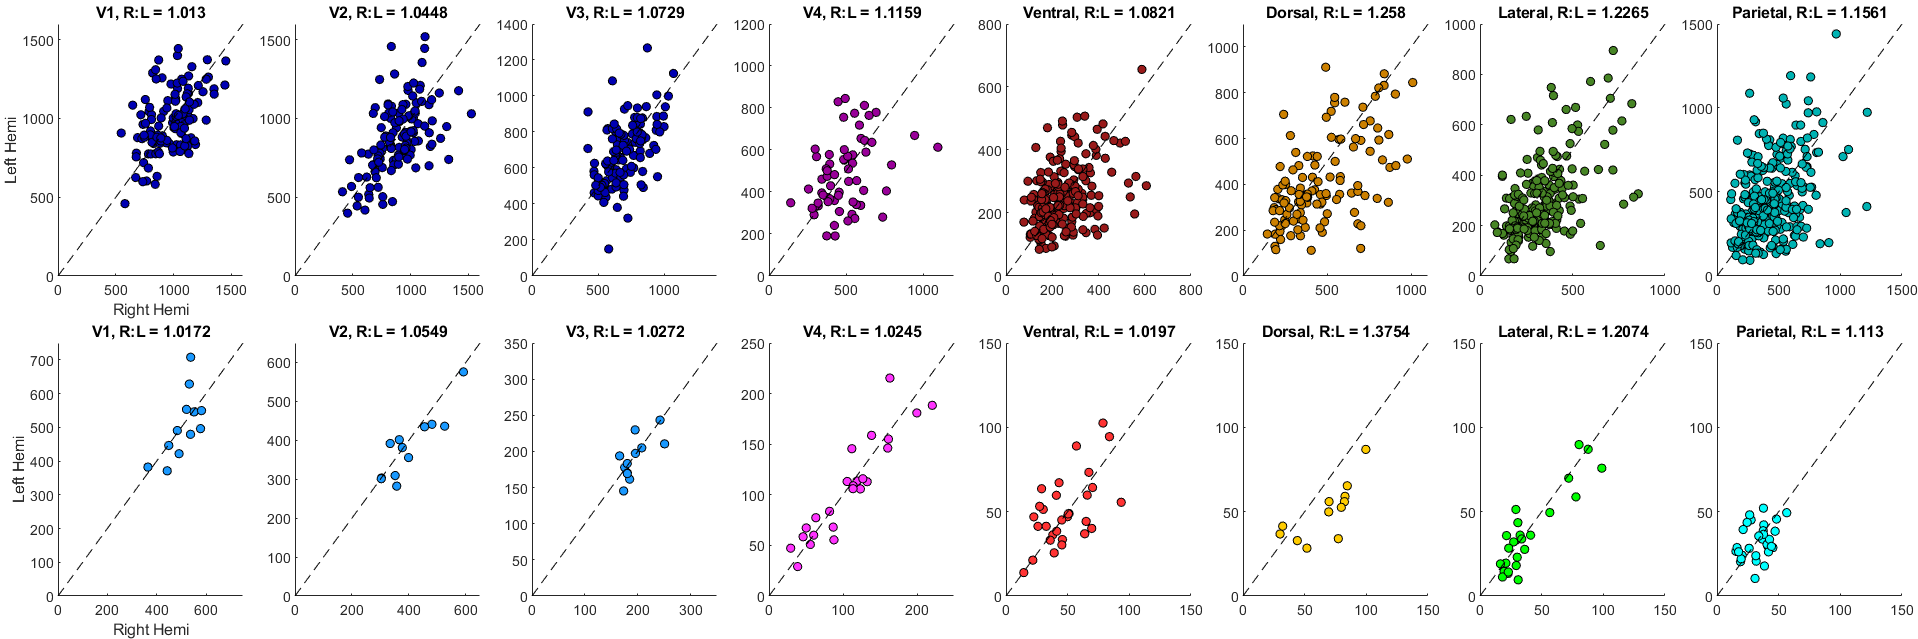

V4rois_human=7;
ventralrois_human=8:11;
dorsalrois_human=12:13;
lateralrois_human=14:17;
parietalrois_human=18:24;
frontalrois_human=25:26;

human_regions = {V1,V2,V3,V4rois_human,ventralrois_human,dorsalrois_human,lateralrois_human,parietalrois_human};
regionName = {'V1','V2','V3','V4','Ventral','Dorsal','Lateral','Parietal'};

figure('Renderer', 'painters', 'Position', [10 10 3000 1000]);
tiledlayout(2,length(human_regions),'Padding',"tight",'TileSpacing','tight');
region_corr_human = zeros(length(human_regions),1);
for i = 1:length(human_regions)
    nexttile;hold on;
    scatter(surfacearea_human{1}(human_regions{i},:),surfacearea_human{2}(human_regions{i},:),25,'ko','MarkerFaceColor',use_colorscale_human(i,:));
    s1 = surfacearea_human{1}(human_regions{i},:);
    s2 = surfacearea_human{2}(human_regions{i},:);
    include = ~isnan(s1(:)) & ~isnan(s2(:));
    region_corr_human(i) = corr2(s1(include),s2(include));
    avgRLratio = mean(surfacearea_human{1}(human_regions{i},:)./surfacearea_human{2}(human_regions{i},:),'all','omitnan');
    maxval = max([max(surfacearea_human{1}(human_regions{i},:),[],'all') max(surfacearea_human{2}(human_regions{i},:),[],'all')]);
    max_round = round(maxval,-2)+100;
    plot([0 max_round],[0 max_round],'k--')
    xlim([0 max_round])
    ylim([0 max_round])
    title([regionName{i},', R:L = ',num2str(avgRLratio)])
    if i == 1
        xlabel('Right Hemi')
        ylabel('Left Hemi')
    end
end

V1=1:2;
V2=3:4;
V3=5:6;
V4rois_monkey=7:10;
ventralrois_monkey=11:15;
dorsalrois_monkey=16:17;
lateralrois_monkey=18:21;
parietalrois_monkey=22:26;

monkey_regions = {V1,V2,V3,V4rois_monkey,ventralrois_monkey,dorsalrois_monkey,lateralrois_monkey,parietalrois_monkey};

region_corr_monkey = zeros(length(monkey_regions),1);
for i = 1:length(monkey_regions)
    nexttile;hold on;
    scatter(surfacearea_monkey{1}(monkey_regions{i},:),surfacearea_monkey{2}(monkey_regions{i},:),25,'ko','MarkerFaceColor',use_colorscale_monkey(i,:));
    s1 = surfacearea_monkey{1}(monkey_regions{i},:);
    s2 = surfacearea_monkey{2}(monkey_regions{i},:);
    include = ~isnan(s1(:)) & ~isnan(s2(:));
    region_corr_monkey(i) = corr2(s1(include),s2(include));
    avgRLratio = mean(surfacearea_monkey{1}(monkey_regions{i},:)./surfacearea_monkey{2}(monkey_regions{i},:),'all');
    maxval = max([max(surfacearea_monkey{1}(monkey_regions{i},:),[],'all') max(surfacearea_monkey{2}(monkey_regions{i},:),[],'all')]);
    max_round = round(maxval,-2)+50;
    plot([0 max_round],[0 max_round],'k--')
    xlim([0 max_round])
    ylim([0 max_round])
    title([regionName{i},', R:L = ',num2str(avgRLratio)])
    if i == 1
        xlabel('Right Hemi')
        ylabel('Left Hemi')
    end
end


human_fig_region_data = [human_fig_region_data array2table(region_corr_human,"VariableNames","Cross-Hemi Corr")];
monkey_fig_region_data = [monkey_fig_region_data array2table(region_corr_monkey,"VariableNames","Cross-Hemi Corr")];


## Hemisphere Comparisons for Each Region

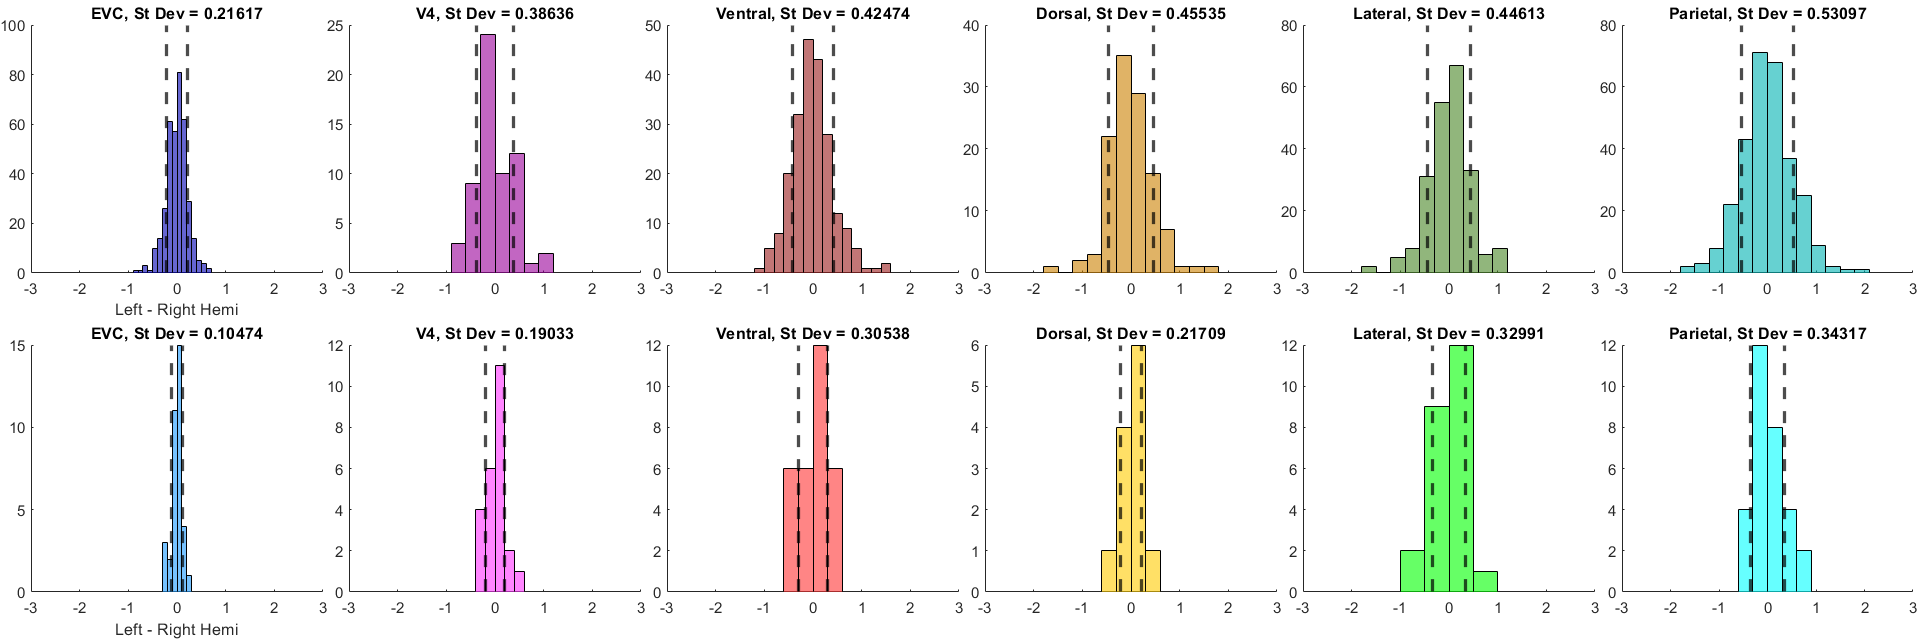

surfacearea_human_norm{1} = surfacearea_human{1} ./ mean(surfacearea_human{1},2,'omitnan');
surfacearea_human_norm{2} = surfacearea_human{2} ./ mean(surfacearea_human{2},2,'omitnan');

surfacearea_monkey_norm{1} = surfacearea_monkey{1} ./ mean(surfacearea_monkey{1},2,'omitnan');
surfacearea_monkey_norm{2} = surfacearea_monkey{2} ./ mean(surfacearea_monkey{2},2,'omitnan');

EVCrois_human=1:6;
V4rois_human=7;
ventralrois_human=8:11;
dorsalrois_human=12:13;
lateralrois_human=14:17;
parietalrois_human=18:24;

human_regions = {EVCrois_human,V4rois_human,ventralrois_human,dorsalrois_human,lateralrois_human,parietalrois_human};
regionName = {'EVC','V4','Ventral','Dorsal','Lateral','Parietal'};

figure('Renderer', 'painters', 'Position', [10 10 3000 1000]);
tiledlayout(2,length(human_regions),'Padding',"tight",'TileSpacing','tight');
for i = 1:length(human_regions)
    nexttile;hold on;
    histogram(surfacearea_human_norm{1}(human_regions{i},:)-surfacearea_human_norm{2}(human_regions{i},:),'FaceColor',use_colorscale_human(i+2,:));
    diff_var = std(surfacearea_human_norm{1}(human_regions{i},:)-surfacearea_human_norm{2}(human_regions{i},:),[],'all','omitnan');
    xline(-diff_var,'k--','LineWidth',2)
    xline(diff_var,'k--','LineWidth',2)
    title([regionName{i}, ', St Dev = ',num2str(diff_var)])
    xlim([-3 3])
    if i == 1
        xlabel('Left - Right Hemi')
    end
end

EVCrois_monkey=1:6;
V4rois_monkey=7:10;
ventralrois_monkey=11:15;
dorsalrois_monkey=16:17;
lateralrois_monkey=18:21;
parietalrois_monkey=22:26;

monkey_regions = {EVCrois_monkey,V4rois_monkey,ventralrois_monkey,dorsalrois_monkey,lateralrois_monkey,parietalrois_monkey};

for i = 1:length(monkey_regions)
    nexttile;hold on;
    histogram(surfacearea_monkey_norm{1}(monkey_regions{i},:)-surfacearea_monkey_norm{2}(monkey_regions{i},:),'FaceColor',use_colorscale_monkey(i+2,:));
    diff_var = std(surfacearea_monkey_norm{1}(monkey_regions{i},:)-surfacearea_monkey_norm{2}(monkey_regions{i},:),[],'all','omitnan');
    xline(-diff_var,'k--','LineWidth',2)
    xline(diff_var,'k--','LineWidth',2)
    title([regionName{i}, ', St Dev = ',num2str(diff_var)])
    xlim([-3 3])
    if i == 1
        xlabel('Left - Right Hemi')
    end
end

## Hemisphere Correlations for V1-V3

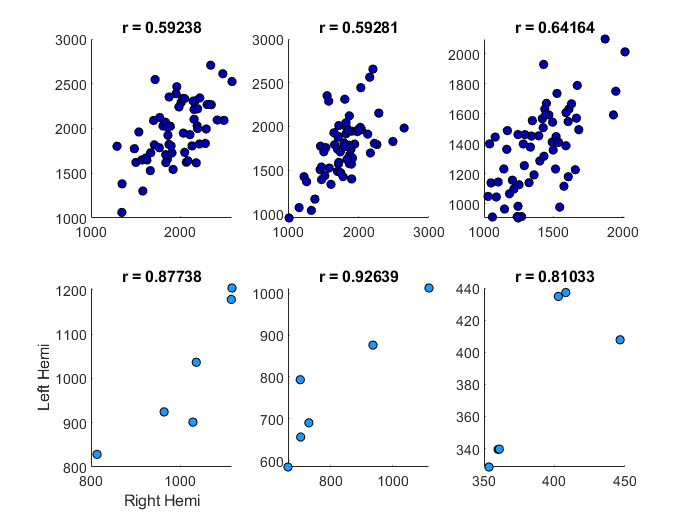

monkey_123{1} = [surfacearea_monkey{1}(1,:)+surfacearea_monkey{1}(2,:);surfacearea_monkey{1}(3,:)+surfacearea_monkey{1}(4,:);surfacearea_monkey{1}(5,:)+surfacearea_monkey{1}(6,:)];
monkey_123{2} = [surfacearea_monkey{2}(1,:)+surfacearea_monkey{2}(2,:);surfacearea_monkey{2}(3,:)+surfacearea_monkey{2}(4,:);surfacearea_monkey{2}(5,:)+surfacearea_monkey{2}(6,:)];

human_123{1} = [surfacearea_human{1}(1,:)+surfacearea_human{1}(2,:);surfacearea_human{1}(3,:)+surfacearea_human{1}(4,:);surfacearea_human{1}(5,:)+surfacearea_human{1}(6,:)];
human_123{2} = [surfacearea_human{2}(1,:)+surfacearea_human{2}(2,:);surfacearea_human{2}(3,:)+surfacearea_human{2}(4,:);surfacearea_human{2}(5,:)+surfacearea_human{2}(6,:)];

figure();
for i = 1:3
    subplot(2,3,i);hold on;
    scatter(human_123{1}(i,:),human_123{2}(i,:),25,'ko','MarkerFaceColor',use_colorscale_human(1,:));
    include = ~isnan(human_123{1}(i,:)) & ~isnan(human_123{2}(i,:));
    r = corr2(human_123{1}(i,include),human_123{2}(i,include));
    title(['r = ',num2str(r)])
%     maxval = max([max(human_123{1}(i,:),[],'all') max(human_123{2}(i,:),[],'all')]);
%     max_round = round(maxval,-2)+50;
%     plot([0 max_round],[0 max_round],'k--')
%     xlim([0 max_round])
%     ylim([0 max_round])
    
    subplot(2,3,i+3);hold on;
    scatter(monkey_123{1}(i,:),monkey_123{2}(i,:),25,'ko','MarkerFaceColor',use_colorscale_monkey(1,:));
    r = corr2(monkey_123{1}(i,:),monkey_123{2}(i,:));
    title(['r = ',num2str(r)])
%     maxval = max([max(monkey_123{1}(i,:),[],'all') max(monkey_123{2}(i,:),[],'all')]);
%     max_round = round(maxval,-2)+50;
%     plot([0 max_round],[0 max_round],'k--')
%     xlim([0 max_round])
%     ylim([0 max_round])
    if i == 1
        xlabel('Right Hemi')
        ylabel('Left Hemi')
    end
end

## Table of area sizes - raw and normalized to V1

% Human values
alllabels_human_merge = {'V1','V2','V3','V4','VO1','VO2','PHC1','PHC2','V3A','V3B','LO1','LO2','TO1','TO2','IPS0','IPS1','IPS2','IPS3','IPS4','IPS5','SPL1'};
array_labels = {'Mean','SE','Min','Max','Mean Norm','SE Norm','Min Norm','Max Norm'};

concat_bothhemi_human = [surfacearea_human{1} surfacearea_human{2}];
surfacearea_human_merge = nan(length(alllabels_human_merge),size(concat_bothhemi_human,2));
surfacearea_human_merge(1,:) = concat_bothhemi_human(1,:)+concat_bothhemi_human(2,:);
surfacearea_human_merge(2,:) = concat_bothhemi_human(3,:)+concat_bothhemi_human(4,:);
surfacearea_human_merge(3,:) = concat_bothhemi_human(5,:)+concat_bothhemi_human(6,:);
surfacearea_human_merge(4:end,:) = concat_bothhemi_human(7:end,:);

surfacearea_human_merge_norm = surfacearea_human_merge./surfacearea_human_merge(1,:);

array_of_values_human = nan(size(surfacearea_human_merge,1),8);
array_of_values_human(:,1) = mean(surfacearea_human_merge,2,'omitnan');
array_of_values_human(:,2) = std(surfacearea_human_merge,[],2,'omitnan')/sqrt(size(surfacearea_human_merge,2));
array_of_values_human(:,3) = min(surfacearea_human_merge,[],2,'omitnan');
array_of_values_human(:,4) = max(surfacearea_human_merge,[],2,'omitnan');

array_of_values_human(:,5) = mean(surfacearea_human_merge_norm,2,'omitnan');
array_of_values_human(:,6) = std(surfacearea_human_merge_norm,[],2,'omitnan')/sqrt(size(surfacearea_human_merge_norm,2));
array_of_values_human(:,7) = min(surfacearea_human_merge_norm,[],2,'omitnan');
array_of_values_human(:,8) = max(surfacearea_human_merge_norm,[],2,'omitnan');
array_of_values_human(:,1:4) = round(array_of_values_human(:,1:4),2);
array_of_values_human(:,5:8) = round(array_of_values_human(:,5:8),4);

table_of_values_human = array2table(array_of_values_human,'VariableNames',array_labels,'RowNames',alllabels_human_merge);

% Monkey values
alllabels_monkey_merge = {'V1','V2','V3','V4','V4A','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','MT','MST','FST','V4t','CIP1','CIP2','LIP1','LIP2','LIP3'};

concat_bothhemi_monkey = [surfacearea_monkey{1} surfacearea_monkey{2}];
surfacearea_monkey_merge = nan(length(alllabels_monkey_merge),size(concat_bothhemi_monkey,2));
surfacearea_monkey_merge(1,:) = concat_bothhemi_monkey(1,:)+concat_bothhemi_monkey(2,:);
surfacearea_monkey_merge(2,:) = concat_bothhemi_monkey(3,:)+concat_bothhemi_monkey(4,:);
surfacearea_monkey_merge(3,:) = concat_bothhemi_monkey(5,:)+concat_bothhemi_monkey(6,:);
surfacearea_monkey_merge(4,:) = concat_bothhemi_monkey(7,:)+concat_bothhemi_monkey(8,:);
surfacearea_monkey_merge(5,:) = concat_bothhemi_monkey(9,:)+concat_bothhemi_monkey(10,:);
surfacearea_monkey_merge(6:end,:) = concat_bothhemi_monkey(11:end,:);

surfacearea_monkey_merge_norm = surfacearea_monkey_merge./surfacearea_monkey_merge(1,:);

array_of_values_monkey = nan(size(surfacearea_monkey_merge,1),8);
array_of_values_monkey(:,1) = mean(surfacearea_monkey_merge,2,'omitnan');
array_of_values_monkey(:,2) = std(surfacearea_monkey_merge,[],2,'omitnan')/sqrt(size(surfacearea_monkey_merge,2));
array_of_values_monkey(:,3) = min(surfacearea_monkey_merge,[],2,'omitnan');
array_of_values_monkey(:,4) = max(surfacearea_monkey_merge,[],2,'omitnan');

array_of_values_monkey(:,5) = mean(surfacearea_monkey_merge_norm,2,'omitnan');
array_of_values_monkey(:,6) = std(surfacearea_monkey_merge_norm,[],2,'omitnan')/sqrt(size(surfacearea_monkey_merge_norm,2));
array_of_values_monkey(:,7) = min(surfacearea_monkey_merge_norm,[],2,'omitnan');
array_of_values_monkey(:,8) = max(surfacearea_monkey_merge_norm,[],2,'omitnan');
array_of_values_monkey(:,1:4) = round(array_of_values_monkey(:,1:4),2);
array_of_values_monkey(:,5:8) = round(array_of_values_monkey(:,5:8),4);

table_of_values_monkey = array2table(array_of_values_monkey,'VariableNames',array_labels,'RowNames',alllabels_monkey_merge);

## Plot Example Correlation of V1 & V2

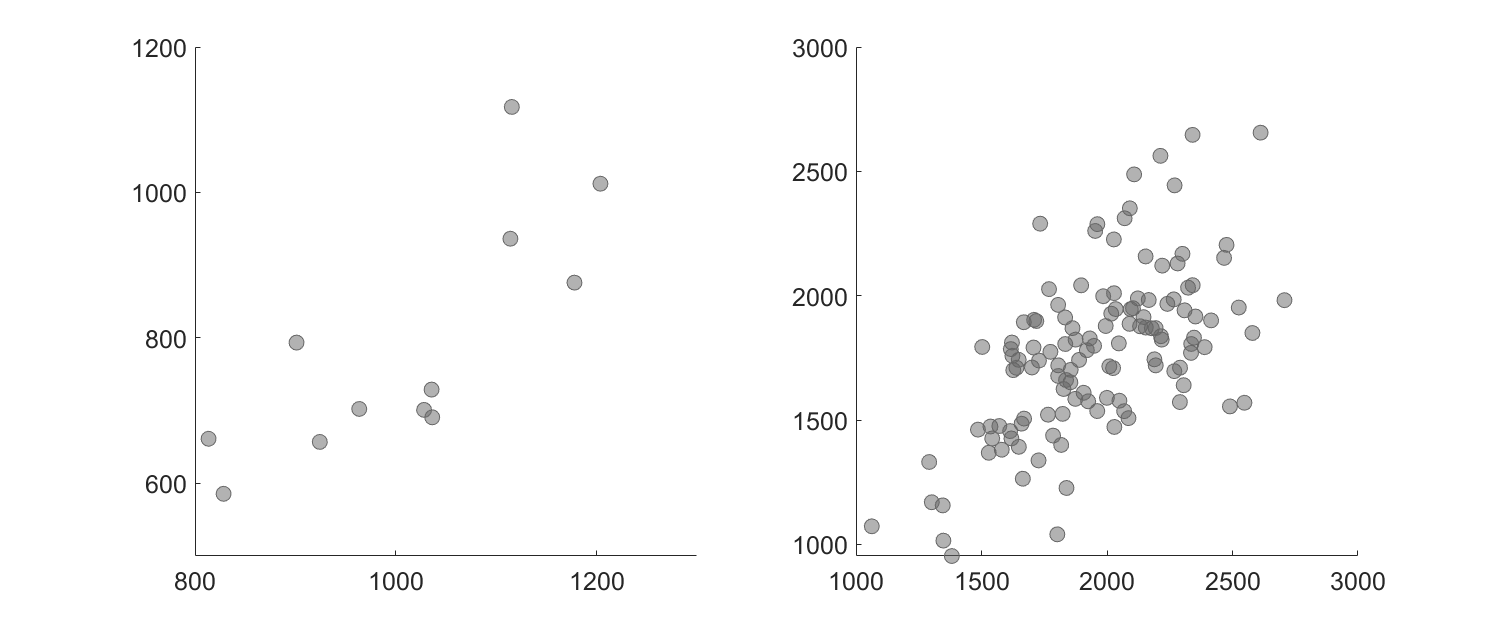

figure('Renderer', 'painters', 'Position', [10 10 1200 500]);
s1 = subplot(1,2,2);
scatter1 = scatter(surfacearea_human_merge(1,:),surfacearea_human_merge(2,:),80,'o','MarkerFaceColor',[0.4 0.4 0.4],'MarkerEdgeColor',[0.4 0.4 0.4]);
scatter1.MarkerFaceAlpha = 0.5;
s1.FontSize = 15;
xticks(1000:500:3000)
yticks(1000:500:3000)
box off

s2 = subplot(1,2,1);
scatter1 = scatter(surfacearea_monkey_merge(1,:),surfacearea_monkey_merge(2,:),80,'o','MarkerFaceColor',[0.4 0.4 0.4],'MarkerEdgeColor',[0.4 0.4 0.4]);
scatter1.MarkerFaceAlpha = 0.5;
s2.FontSize = 15;
xticks(800:200:1400)
yticks(400:200:1400)
box off

## Fig 4 A&B: Correlation Matrix Across All Areas - Human & Monkey

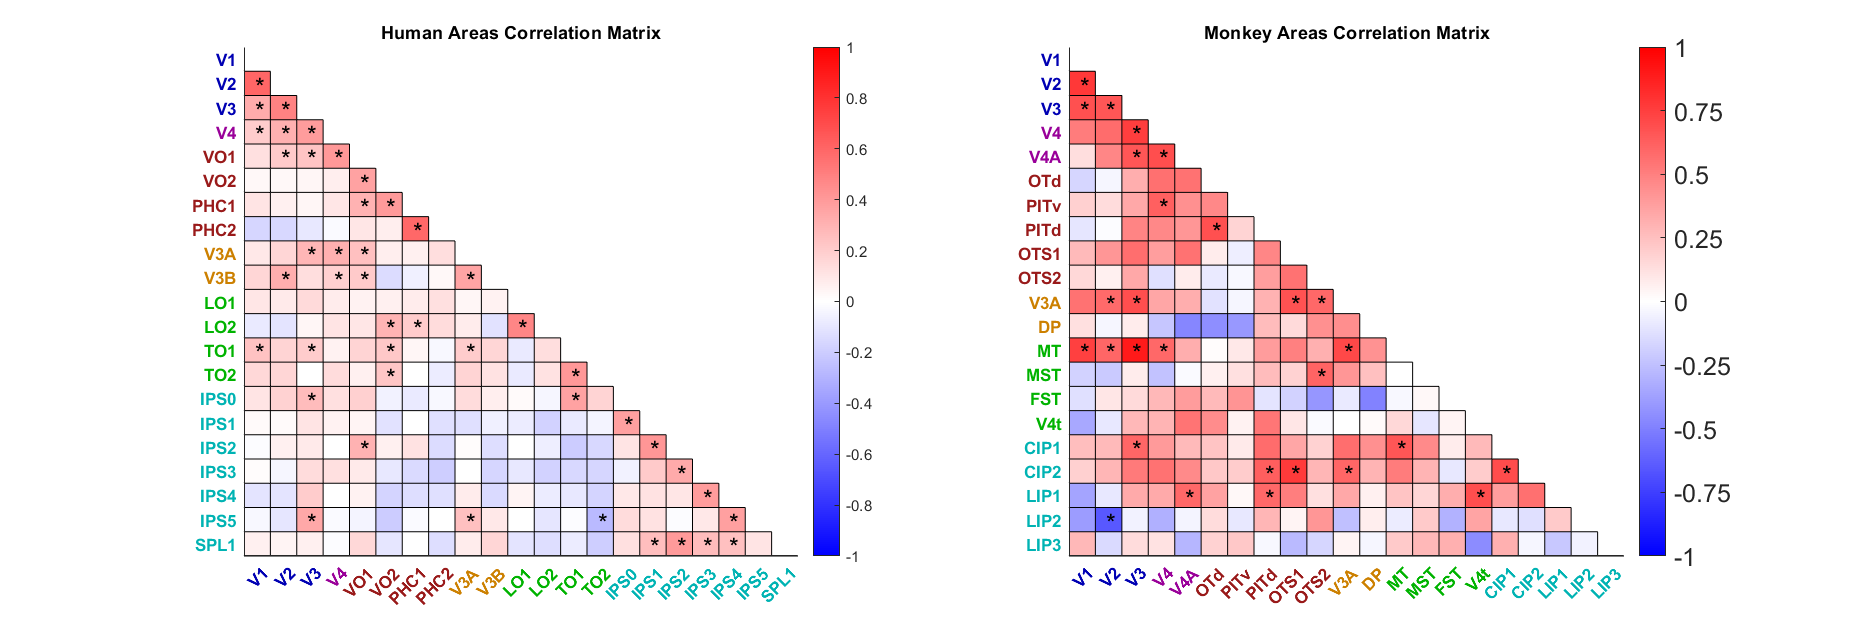

all_area_corr_human = zeros(length(alllabels_human_merge),length(alllabels_human_merge));
all_area_pval_human = zeros(length(alllabels_human_merge),length(alllabels_human_merge));
for i = 1:length(alllabels_human_merge)
    for j = 1:length(alllabels_human_merge)
        include = ~isnan(surfacearea_human_merge(i,:)) & ~isnan(surfacearea_human_merge(j,:));
        [r,p] = corr(surfacearea_human_merge(i,include)',surfacearea_human_merge(j,include)');
        all_area_pval_human(i,j) = p;
        all_area_corr_human(i,j) = r;
    end
end

all_area_corr_monkey = zeros(length(alllabels_monkey_merge),length(alllabels_monkey_merge));
all_area_pval_monkey = zeros(length(alllabels_monkey_merge),length(alllabels_monkey_merge));
for i = 1:length(alllabels_monkey_merge)
    for j = 1:length(alllabels_monkey_merge)
        include = ~isnan(surfacearea_monkey_merge(i,:)) & ~isnan(surfacearea_monkey_merge(j,:));
        [r,p] = corr(surfacearea_monkey_merge(i,include)',surfacearea_monkey_merge(j,include)');
        all_area_pval_monkey(i,j) = p;
        all_area_corr_monkey(i,j) = r;
    end
end

human_fig_data = [human_fig_data array2table(all_area_corr_human(:,1),"VariableNames","Corr w V1")];
monkey_fig_data = [monkey_fig_data array2table(all_area_corr_monkey(:,1),"VariableNames","Corr w V1")];

EVCcolor=[0 0 0.7];
V4color=[0.6 0 0.6];
ventralcolor=[0.6 0.1 0.1];
dorsalcolor=[0.8 .5 0]; % added V7, idk if that's right
lateralcolor=[0 0.7 0];
parietalcolor=[0 0.7 0.7];
frontalcolor=[.4 0 .4];

figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
subplot(1,2,1)
Z = ones(size(all_area_corr_human,1), size(all_area_corr_human,2), 3);  %black background
image(Z);
hold on;
lower_tri = tril(all_area_corr_human);
lower_tri(1:length(lower_tri)+1:end) = 0;
p_tri = tril(all_area_pval_human);
p_tri(p_tri == 0) = 1;
p_tri(1:length(p_tri)+1:end) = 1;
alphadata = double(lower_tri ~= 0);

h1 = imagesc(all_area_corr_human);
h1.AlphaData = alphadata;
% hold off
for i = 1:size(all_area_corr_human,1)
    for j = 1:size(all_area_corr_human,2)
        if p_tri(j,i)<0.05
            text(i-0.1,j+0.1,'*','FontSize',15)
        end
        if j < length(all_area_corr_human)
        plot([j+0.5 j+0.5],[j+0.5 length(all_area_corr_human)+0.5],'k')
        end
    end
    plot([i+0.5 0],[i+0.5 i+0.5],'k')
end
Xticklabels_new = cell(size(alllabels_human_merge));
Yticklabels_new = cell(size(alllabels_human_merge));
for i = 1:3
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], EVCcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], EVCcolor);
end
for i = 4
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], V4color);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], V4color);
end
for i = 5:8
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], ventralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], ventralcolor);
end
for i = 9:10
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], dorsalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], dorsalcolor);
end
for i = 11:14
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], lateralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], lateralcolor);
end
for i = 15:21
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], parietalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], parietalcolor);
end

ax = gca;
set(ax, 'XTick',1:length(alllabels_human_merge),'XTickLabel',Xticklabels_new)
set(ax, 'YTick',1:length(alllabels_human_merge),'YTickLabel',Yticklabels_new)
% set(ax,'xaxisLocation','top')
box off;
ax.XAxis.TickLength = [0 0];
ax.YAxis.TickLength = [0 0];

colormap(redblue);c = colorbar;caxis([-1 1]);
title('Human Areas Correlation Matrix')

subplot(1,2,2);
Z = ones(size(all_area_corr_monkey,1), size(all_area_corr_monkey,2), 3);  %black background
image(Z);
hold on;
lower_tri = tril(all_area_corr_monkey);
lower_tri(1:length(lower_tri)+1:end) = 0;
alphadata = double(lower_tri ~= 0);
p_tri = tril(all_area_pval_monkey);
p_tri(p_tri == 0) = 1;
p_tri(1:length(p_tri)+1:end) = 1;

h2 = imagesc(all_area_corr_monkey);
h2.AlphaData = alphadata;
% hold off
for i = 1:size(all_area_corr_monkey,1)
    for j = 1:size(all_area_corr_monkey,2)
        if p_tri(j,i)<0.05
            text(i-0.1,j+0.1,'*','FontSize',15)
        end
        if j < length(all_area_corr_monkey)
        plot([j+0.5 j+0.5],[j+0.5 length(all_area_corr_monkey)+0.5],'k')
        end
    end
    plot([i+0.5 0],[i+0.5 i+0.5],'k')    
end

% Xticklabels = get(gca,'XDisplayLabels');
Xticklabels_new = cell(size(alllabels_monkey_merge));
% Yticklabels = get(gca,'YDisplayLabels');
Yticklabels_new = cell(size(alllabels_monkey_merge));
for i = 1:3
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey_merge{i},'}'], EVCcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey_merge{i},'}'], EVCcolor);
end
for i = 4:5
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey_merge{i},'}'], V4color);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey_merge{i},'}'], V4color);
end
for i = 6:10
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey_merge{i},'}'], ventralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey_merge{i},'}'], ventralcolor);
end
for i = 11:12
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey_merge{i},'}'], dorsalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey_merge{i},'}'], dorsalcolor);
end
for i = 13:16
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey_merge{i},'}'], lateralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey_merge{i},'}'], lateralcolor);
end
for i = 17:21
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey_merge{i},'}'], parietalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey_merge{i},'}'], parietalcolor);
end
ax = gca;
set(ax, 'XTick',1:length(alllabels_monkey_merge),'XTickLabel',Xticklabels_new)
set(ax, 'YTick',1:length(alllabels_monkey_merge),'YTickLabel',Yticklabels_new)
box off;
ax.XAxis.TickLength = [0 0];
ax.YAxis.TickLength = [0 0];
% set(ax,'xaxisLocation','top')
colormap(redblue);c = colorbar;caxis([-1 1]);c.Ticks = -1:0.25:1;c.FontSize = 15;

title('Monkey Areas Correlation Matrix')

## Fig 4C: Correlations of visual areas with V1

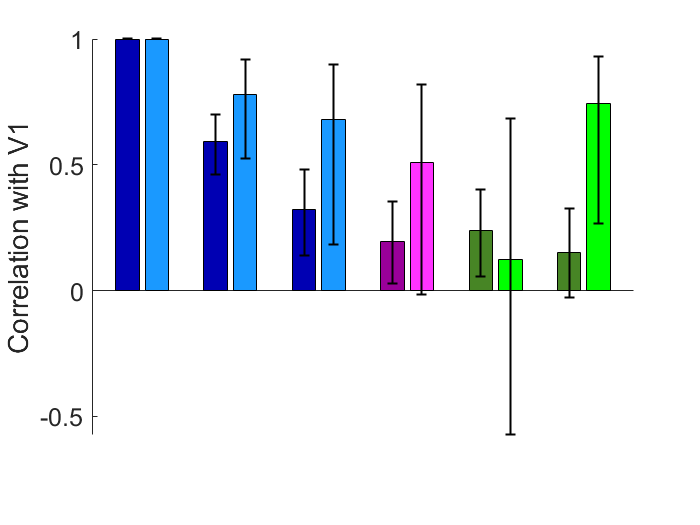

% should probably do some bootstrapping here
all_area_corr_human = zeros(length(alllabels_human_merge),length(alllabels_human_merge));
all_area_pval_human = zeros(length(alllabels_human_merge),length(alllabels_human_merge));
stats_human = zeros(length(alllabels_human_merge),length(alllabels_human_merge),2);
for i = 1:length(alllabels_human_merge)
    for j = 1:length(alllabels_human_merge)
        include = ~isnan(surfacearea_human_merge(i,:)) & ~isnan(surfacearea_human_merge(j,:));
        [r,p] = corr(surfacearea_human_merge(i,include)',surfacearea_human_merge(j,include)');
        temp = bootci(1000,@corr,[surfacearea_human_merge(i,include)',surfacearea_human_merge(j,include)']);
        stats_human(i,j,:) = temp(:,1,2);
        all_area_pval_human(i,j) = p;
        all_area_corr_human(i,j) = r;
    end
end

all_area_corr_monkey = zeros(length(alllabels_monkey_merge),length(alllabels_monkey_merge));
all_area_pval_monkey = zeros(length(alllabels_monkey_merge),length(alllabels_monkey_merge));
stats_monkey = zeros(length(alllabels_human_merge),length(alllabels_human_merge),2);
for i = 1:length(alllabels_monkey_merge)
    for j = 1:length(alllabels_monkey_merge)
        include = ~isnan(surfacearea_monkey_merge(i,:)) & ~isnan(surfacearea_monkey_merge(j,:));
        [r,p] = corr(surfacearea_monkey_merge(i,include)',surfacearea_monkey_merge(j,include)');
        temp = bootci(1000,@corr,[surfacearea_monkey_merge(i,include)',surfacearea_monkey_merge(j,include)']);
        stats_monkey(i,j,:) = temp(:,1,2);
        all_area_pval_monkey(i,j) = p;
        all_area_corr_monkey(i,j) = r;
    end
end

xlab = {'V1','V2','V3','V4','TO1/MT','TO2/MST'};
h_idx = [1:4,13,14];m_idx = [1:4,12,13];
hx = 1:3:3*6;mx = 2:3:3*6+1;
all_area_corr = [all_area_corr_human(h_idx,1), all_area_corr_monkey(m_idx,1)];
h_color = [use_colorscale_human([1:4,7],:);use_colorscale_human(7,:)];
m_color = [use_colorscale_monkey([1:4,7],:);use_colorscale_monkey(7,:)];

figure;hold on;
for i = 1:length(h_idx)
    bar(hx(i),all_area_corr_human(h_idx(i),1),'FaceColor',h_color(i,:));
    errorbar(hx(i),all_area_corr_human(h_idx(i),1),all_area_corr_human(h_idx(i),1)-stats_human(h_idx(i),1,1),stats_human(h_idx(i),1,2)-all_area_corr_human(h_idx(i),1),'k','LineWidth',1.2)
end
for i = 1:length(m_idx)
    bar(mx(i),all_area_corr_monkey(m_idx(i),1),'FaceColor',m_color(i,:));
    errorbar(mx(i),all_area_corr_monkey(m_idx(i),1),all_area_corr_monkey(m_idx(i),1)-stats_monkey(m_idx(i),1,1),stats_monkey(m_idx(i),1,2)-all_area_corr_monkey(m_idx(i),1),'k','LineWidth',1.2)
end
xticks(1.5:3:3*7)
xticklabels(xlab)
ax = gca;
% ax.XAxis.TickLength = [0 0];
% set(gca,'xtick',[])
ax.XAxis.Visible = 'off';
ax.FontSize = 15;
ylabel('Correlation with V1')
% legend('Human','Monkey')
box off

## Comparing Cross-Species Normalized Area Sizes

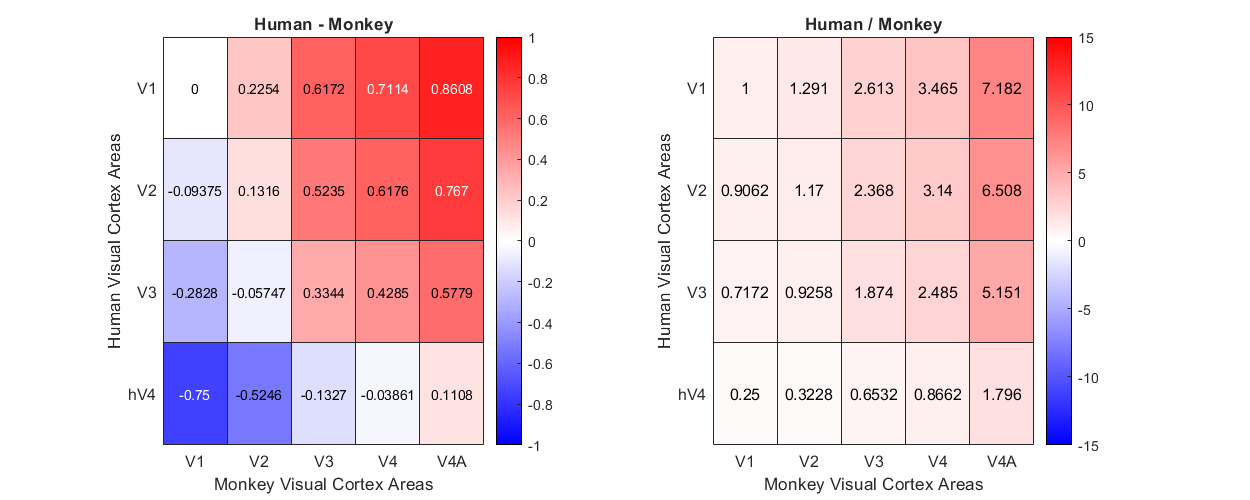

VCrois_human = {'V1','V2','V3','hV4'};
VCrois_monkey = {'V1','V2','V3','V4','V4A'};

ventralrois_human=(8:11)-3;
dorsalrois_human=(12:13)-3;
lateralrois_human=(14:17)-3;
parietalrois_human=(18:24)-3;

ventralrois_monkey=(11:15)-5;
dorsalrois_monkey=(16:17)-5;
lateralrois_monkey=(18:21)-5;
parietalrois_monkey=(22:26)-5;

nhuman = length(VCrois_human);
nmonkey = length(VCrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
roi_div = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(hh,:),'omitnan');
        avgmonkey = mean(normv1_monkey(mm,:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
        roi_div(hh,mm) = avghuman / avgmonkey;
    end
end

yvalues = VCrois_human;
xvalues = VCrois_monkey;

figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
subplot(1,2,1)
h = heatmap(xvalues,yvalues,roi_diff);
colormap(redblue);colorbar;caxis([-1 1]);
xlabel('Monkey Visual Cortex Areas')
ylabel('Human Visual Cortex Areas')
title('Human - Monkey')

subplot(1,2,2)
h = heatmap(xvalues,yvalues,roi_div);
colormap(redblue);colorbar;caxis([-15 15]);
xlabel('Monkey Visual Cortex Areas')
ylabel('Human Visual Cortex Areas')
title('Human / Monkey')

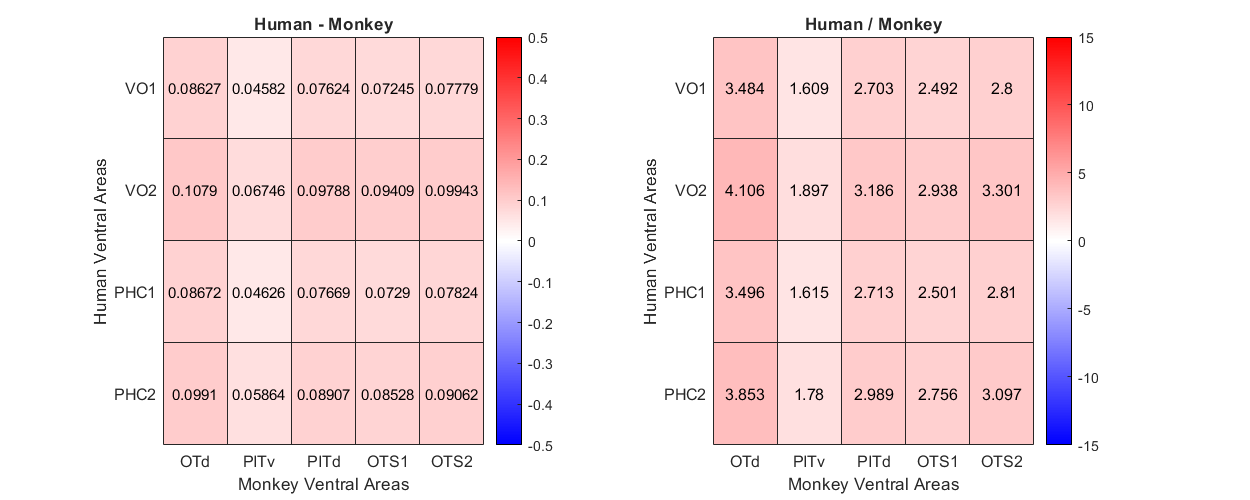


% ventral rois
nhuman = length(ventralrois_human);
nmonkey = length(ventralrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
roi_div = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(ventralrois_human(hh),:),'omitnan');
        avgmonkey = mean(normv1_monkey(ventralrois_monkey(mm),:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
        roi_div(hh,mm) = avghuman / avgmonkey;
    end
end

yvalues = alllabels_human_merge(ventralrois_human);
xvalues = alllabels_monkey_merge(ventralrois_monkey);

figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
subplot(1,2,1)
h = heatmap(xvalues,yvalues,roi_diff);
colormap(redblue);colorbar;caxis([-0.5 0.5]);
xlabel('Monkey Ventral Areas')
ylabel('Human Ventral Areas')
title('Human - Monkey')

subplot(1,2,2)
h = heatmap(xvalues,yvalues,roi_div);
colormap(redblue);colorbar;caxis([-15 15]);
xlabel('Monkey Ventral Areas')
ylabel('Human Ventral Areas')
title('Human / Monkey')

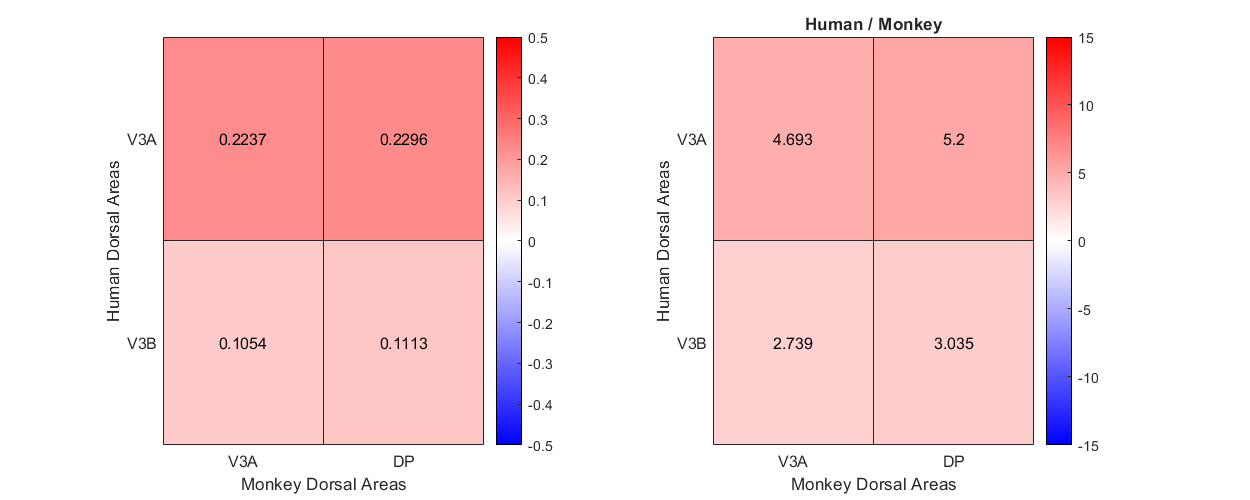


% dorsal rois
nhuman = length(dorsalrois_human);
nmonkey = length(dorsalrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
roi_div = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(dorsalrois_human(hh),:),'omitnan');
        avgmonkey = mean(normv1_monkey(dorsalrois_monkey(mm),:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
        roi_div(hh,mm) = avghuman / avgmonkey;
    end
end

yvalues = alllabels_human_merge(dorsalrois_human(1:2));
xvalues = alllabels_monkey_merge(dorsalrois_monkey);

figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
subplot(1,2,1);
h = heatmap(xvalues,yvalues,roi_diff);
colormap(redblue);colorbar;caxis([-0.5 0.5]);
xlabel('Monkey Dorsal Areas')
ylabel('Human Dorsal Areas')

subplot(1,2,2)
h = heatmap(xvalues,yvalues,roi_div);
colormap(redblue);colorbar;caxis([-15 15]);
xlabel('Monkey Dorsal Areas')
ylabel('Human Dorsal Areas')
title('Human / Monkey')

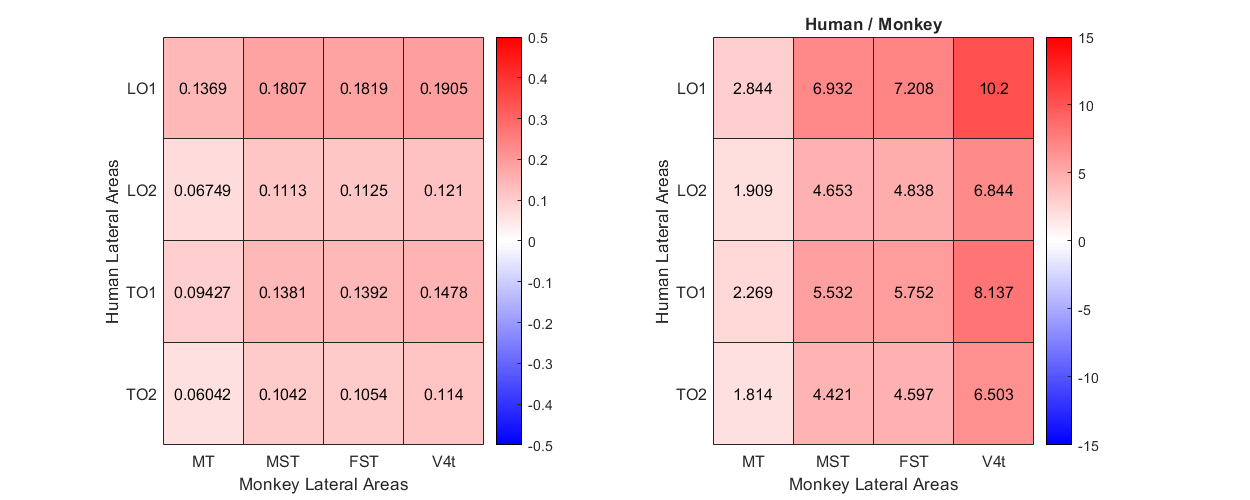


% lateral rois
nhuman = length(lateralrois_human);
nmonkey = length(lateralrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
roi_div = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(lateralrois_human(hh),:),'omitnan');
        avgmonkey = mean(normv1_monkey(lateralrois_monkey(mm),:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
        roi_div(hh,mm) = avghuman / avgmonkey;
    end
end

yvalues = alllabels_human_merge(lateralrois_human);
xvalues = alllabels_monkey_merge(lateralrois_monkey);

figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
subplot(1,2,1);
h = heatmap(xvalues,yvalues,roi_diff);
colormap(redblue);colorbar;caxis([-0.5 0.5]);
xlabel('Monkey Lateral Areas')
ylabel('Human Lateral Areas')

subplot(1,2,2)
h = heatmap(xvalues,yvalues,roi_div);
colormap(redblue);colorbar;caxis([-15 15]);
xlabel('Monkey Lateral Areas')
ylabel('Human Lateral Areas')
title('Human / Monkey')

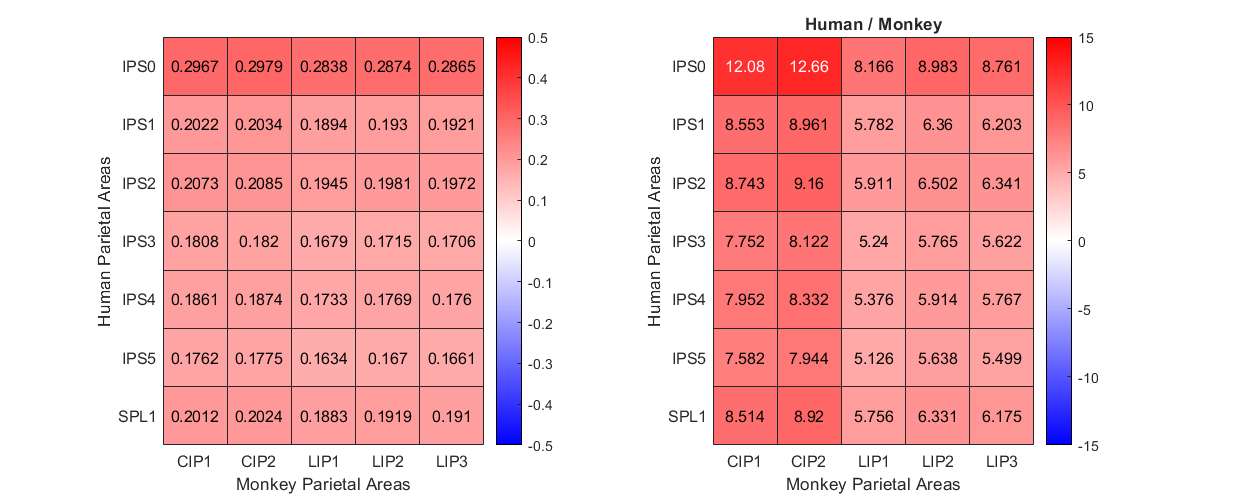


% parietal rois
nhuman = length(parietalrois_human);
nmonkey = length(parietalrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
roi_div = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(parietalrois_human(hh),:),'omitnan');
        avgmonkey = mean(normv1_monkey(parietalrois_monkey(mm),:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
        roi_div(hh,mm) = avghuman / avgmonkey;
    end
end

yvalues = alllabels_human_merge(parietalrois_human);
xvalues = alllabels_monkey_merge(parietalrois_monkey);

figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
subplot(1,2,1);
h = heatmap(xvalues,yvalues,roi_diff);
colormap(redblue);colorbar;caxis([-0.5 0.5]);
xlabel('Monkey Parietal Areas')
ylabel('Human Parietal Areas')

subplot(1,2,2)
h = heatmap(xvalues,yvalues,roi_div);
colormap(redblue);colorbar;caxis([-15 15]);
xlabel('Monkey Parietal Areas')
ylabel('Human Parietal Areas')
title('Human / Monkey')